# Skin Lesion Detection

### Muhammad Asmar

### Muhammad Ahmed

## Prepare Training and Validation Datasets

% Import training data images
imdsTrain = imageDatastore("train", "IncludeSubfolders", true, "LabelSource", "foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain, 0.8, "randomized");
numClasses = numel(categories(imdsTrain.Labels));

% Augment the training images with rotation, scale, and reflection
imageAugmenter = imageDataAugmenter(...
    "RandRotation", [-90 90],...
    "RandScale", [1 1.5],...
    "RandXReflection", true);

## Construct Network

% Interactively ask for model
model = "googlenet";
if strcmp(model, "googlenet")
    net = googlenet;
elseif strcmp(model, "resnet50")
    net = resnet50;
elseif strcmp(model, "nasnetmobile")
    net = nasnetmobile;
elseif strcmp(model, "densenet201")
    net = densenet201;
elseif strcmp(model, "inceptionresnetv2")
    net = inceptionresnetv2;
end

% Replace last three layers in DAG Network
lgraph = layerGraph(net);
lgraph = replaceLayer(lgraph, net.Layers(end-2, 1).Name, fullyConnectedLayer(numClasses));
lgraph = replaceLayer(lgraph, net.Layers(end-1, 1).Name, softmaxLayer);
lgraph = replaceLayer(lgraph, net.Layers(end, 1).Name, classificationLayer);
inputSize = net.Layers(1).InputSize;

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore(inputSize, imdsTrain, "DataAugmentation", imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize, imdsValidation);

% Set training parameters
opts = trainingOptions("sgdm",...
    "ExecutionEnvironment", "auto",...
    "InitialLearnRate", 0.0001,...
    "MaxEpochs", 20,...
    "MiniBatchSize", 100,...
    "Shuffle", "every-epoch",...
    "ValidationFrequency", 5,...
    "Plots", "training-progress",...
    "ValidationData", augimdsValidation);

## Train Network and Display Results

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


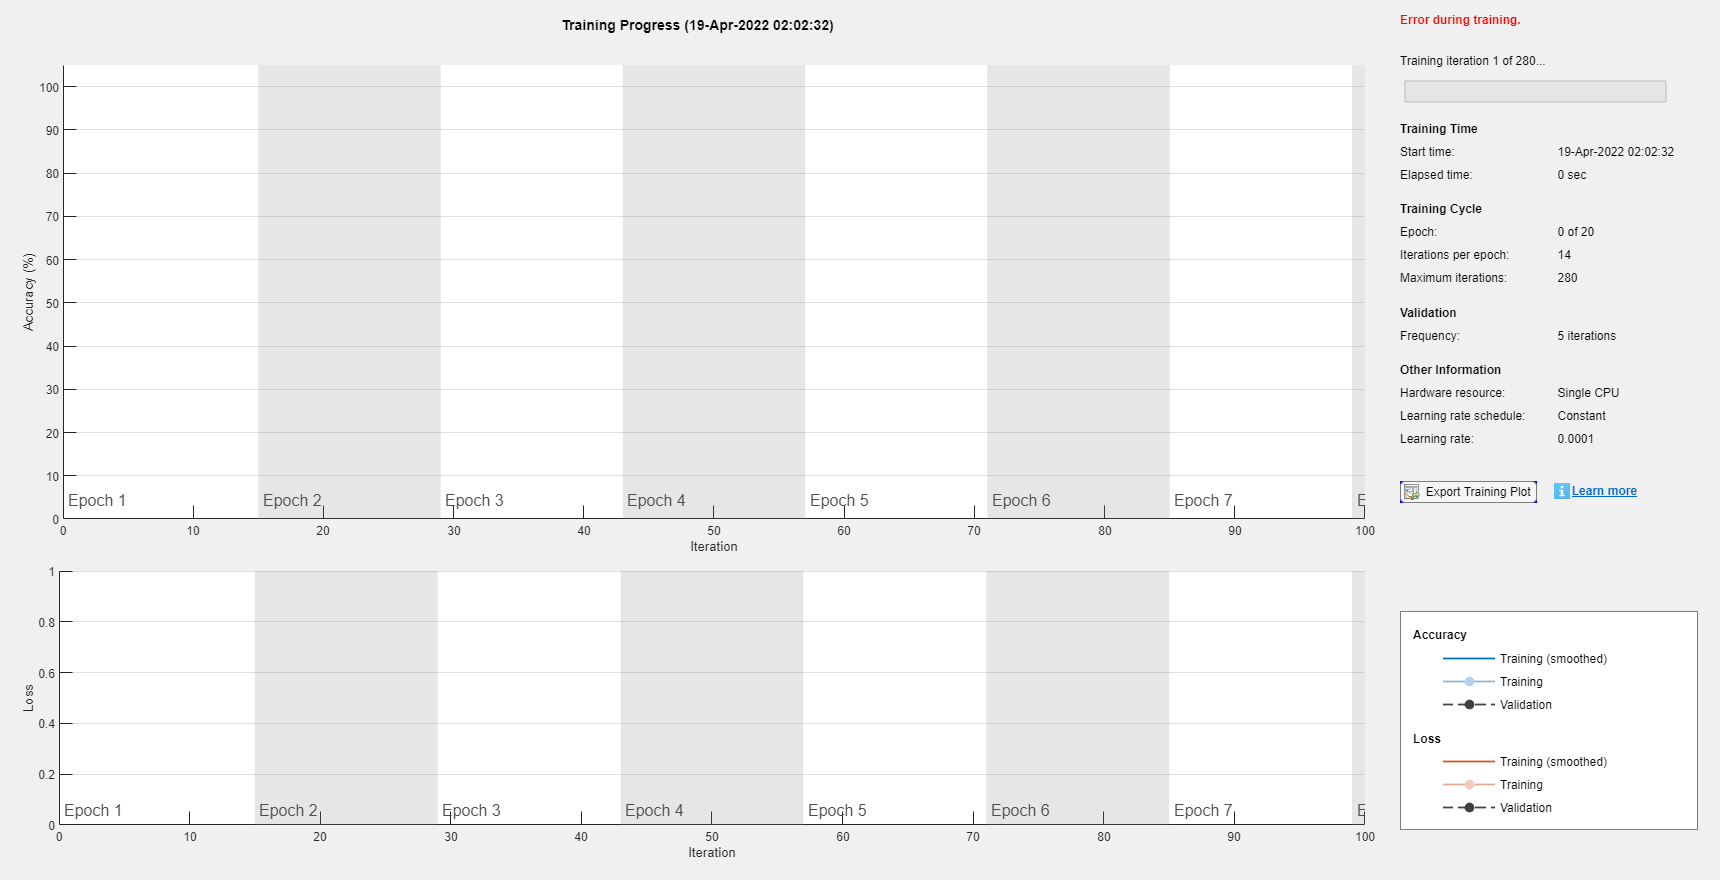

Error using trainNetwork
Out of memory.

Caused by:
    Error using builtin
    Out of memory.

% Train new network
[netTransfer, info] = trainNetwork(augimdsTrain, lgraph, opts);

% Calculate classification accuracy
[YPred, probs] = classify(net, augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels);
fprintf("Validation Accuracy: %.2f", accuracy)